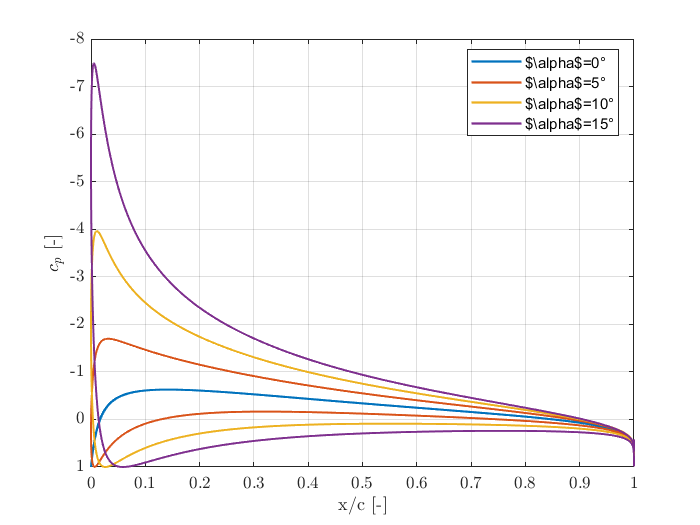

%analysis of results
feature('DefaultCharacterSet','UTF8');
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex'); 
set(groot, 'defaultTextInterpreter', 'latex');
set(groot, 'defaultTextFontsize',13);
set(groot, 'defaultAxesFontsize',13);
set(groot, 'defaultLegendFontsize',13);
set(groot, 'defaultLegendLocation','best');
set(0, 'DefaultLineLineWidth', 1.3);
pt = 12;
%evolution of the cl wrt the angle of attack and cp wrt x/c.
NACA=[0 0 1 8];
c=1;
V_inf=50;
alpha=[-15 -10 -5 0 5 10 15]*pi/180;
cl_vec=zeros(7,1);
for i=1:7
    [cl,cp,X,N]=my_panel_method(NACA,c,alpha(i),V_inf);
    cl_vec(i)=cl;
    if i>=4
        plot(X(1:N)/c,cp);
        hold on
       
    end
end
set(gca, 'YDir','reverse');
grid on
xlabel('x/c [-]');
ylabel('$c_p$ [-]');
legend('$\alpha$=0°','$\alpha$=5°','$\alpha$=10°','$\alpha$=15°');
hold off

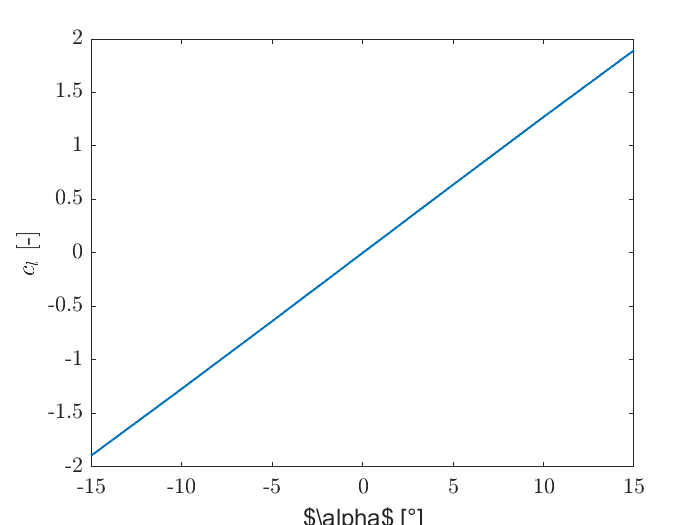

plot(alpha*180/pi,cl_vec);
xlabel('$\alpha$ [°]');
ylabel('$c_l$ [-]');